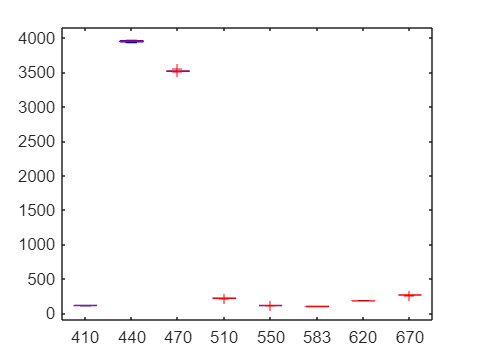

AS_wavelengths = [410, 440, 470, 510, 550, 583, 620, 670];
VEML_wavelengths = [650, 550, 450];
b = 50;
BLUE_Scaled = scale(BLUE);
[BLUE_10_AS, BLUE_10_VEML] = retrieve_int(BLUE_Scaled, b);
boxplot(transpose(BLUE_10_AS(1:8,:)),AS_wavelengths);

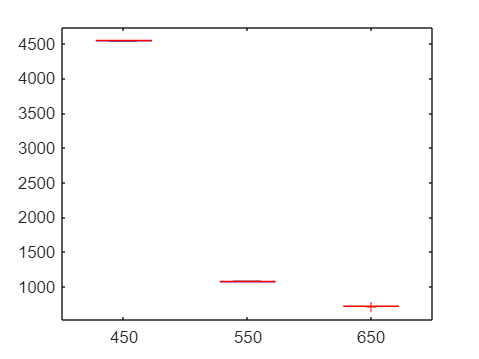

boxplot(transpose(BLUE_10_VEML(1:3,:)),VEML_wavelengths);

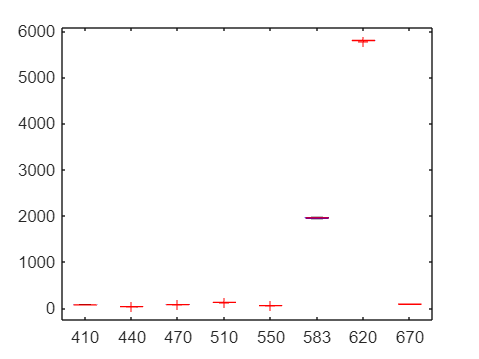


RED_Scaled = scale(RED);
[RED_10_AS, RED_10_VEML] = retrieve_int(RED_Scaled, b);
boxplot(transpose(RED_10_AS(1:8,:)),AS_wavelengths);

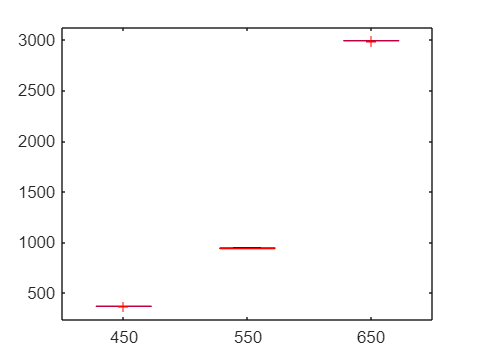

boxplot(transpose(RED_10_VEML(1:3,:)),VEML_wavelengths);


sum(RED_10_AS(1:8,1))

ans = 8.1938e+03

RED_10_AS(9,1)

ans = 3.4224e+03

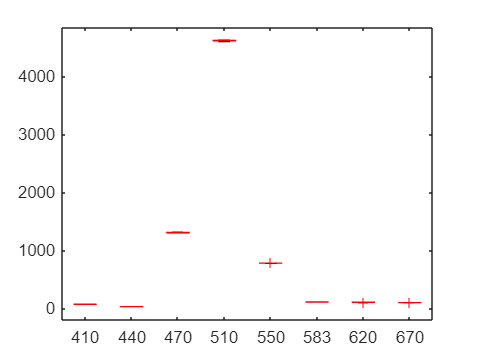


GREEN_Scaled = scale(GREEN);
[GREEN_10_AS, GREEN_10_VEML] = retrieve_int(GREEN_Scaled, b);
boxplot(transpose(GREEN_10_AS(1:8,:)),AS_wavelengths);

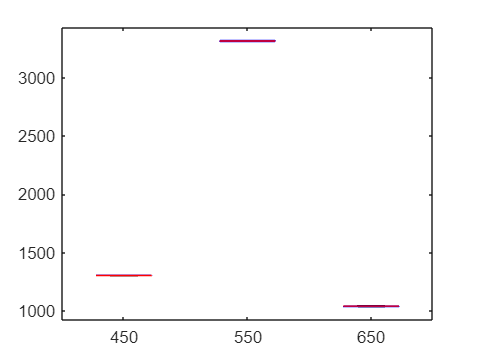

boxplot(transpose(GREEN_10_VEML(1:3,:)),VEML_wavelengths);

WHITE_Scaled = scale(WHITE);
[WHITE_10_AS, WHITE_10_VEML] = retrieve_int(WHITE_Scaled, b);
boxplot(transpose(WHITE_10_AS(1:8,:)),AS_wavelengths);
boxplot(transpose(WHITE_10_VEML(1:3,:)),VEML_wavelengths);

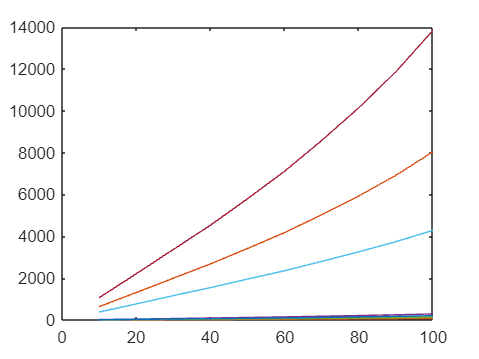

[RED_Brightness_160_AS, RED_Brightness_160_VEML] = retrieve_brightness(RED_Scaled, 3);
plot(10:10:100, RED_Brightness_160_AS);

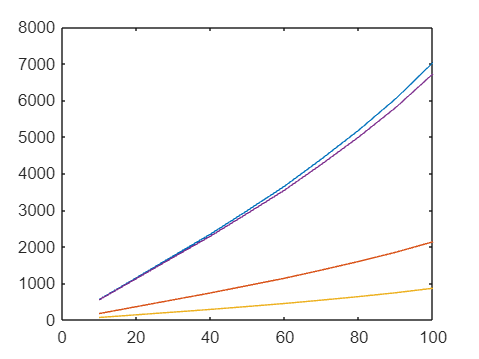


plot(10:10:100, RED_Brightness_160_VEML);

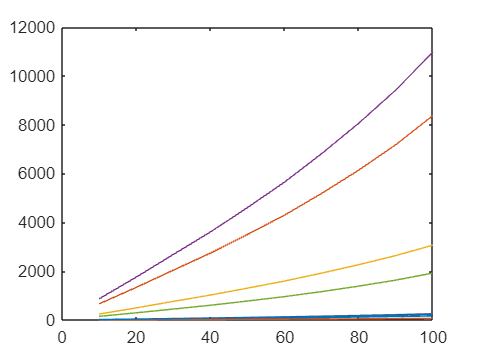


[GREEN_Brightness_160_AS, GREEN_Brightness_160_VEML] = retrieve_brightness(GREEN_Scaled, 3);
plot(10:10:100, GREEN_Brightness_160_AS);

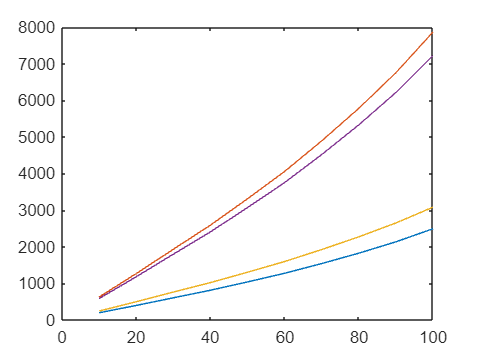

plot(10:10:100, GREEN_Brightness_160_VEML);

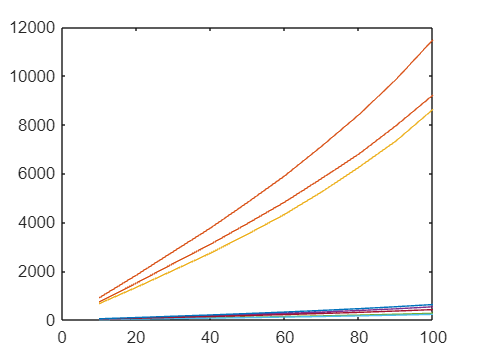


[BLUE_Brightness_160_AS, BLUE_Brightness_160_VEML] = retrieve_brightness(BLUE_Scaled, 3);
plot(10:10:100, BLUE_Brightness_160_AS);

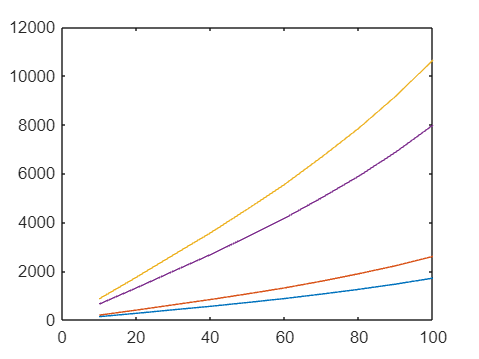

plot(10:10:100, BLUE_Brightness_160_VEML);

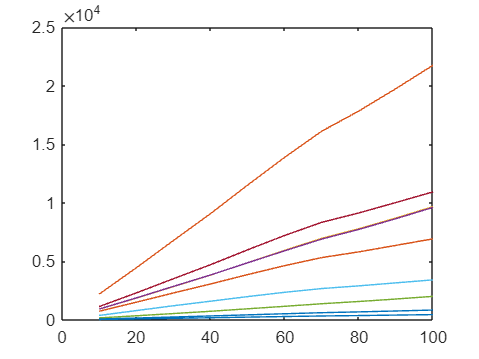


[WHITE_Brightness_160_AS, WHITE_Brightness_160_VEML] = retrieve_brightness(WHITE_Scaled, 3);
plot(10:10:100, WHITE_Brightness_160_AS);

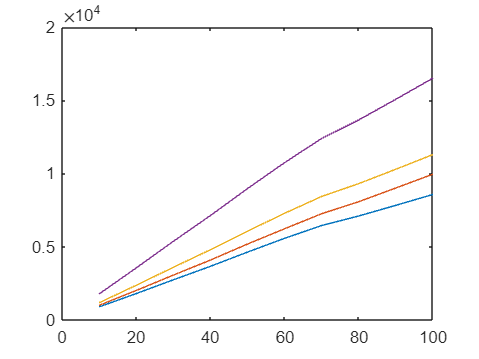

plot(10:10:100, WHITE_Brightness_160_VEML);

function COLOUR_Scaled = scale(COLOUR)
    factors = [4, 2, 1, 0.5, 0.25, 0.125];
    COLOUR_Scaled = cell(10,6);
    for j = 1:10
        for i = 1:6
            COLOUR_Scaled{j,i} = COLOUR{j, i}.*factors(i);
        end
    end
end

function [COLOUR_BRIGHTNESS_AS, COLOUR_BRIGHTNESS_VEML] = retrieve_int(COLOUR_Scaled, brightness)
    COLOUR_BRIGHTNESS_AS = zeros(9,6);
    COLOUR_BRIGHTNESS_VEML = zeros(4,6);
    for j = 1:9
        for i = 1:6
            COLOUR_BRIGHTNESS_AS(j,i) = COLOUR_Scaled{brightness/10,i}(1,j);
        end
    end
    for j = 1:4
        for i = 1:6
            COLOUR_BRIGHTNESS_VEML(j,i) = COLOUR_Scaled{brightness/10,i}(1,j+10);
        end
    end
end

function [COLOUR_BRIGHTNESS_AS, COLOUR_BRIGHTNESS_VEML] = retrieve_brightness(COLOUR_Scaled, integration_time)
    COLOUR_BRIGHTNESS_AS = zeros(9,10);
    COLOUR_BRIGHTNESS_VEML = zeros(4,10);
    for j = 1:9
        for i = 1:10
            COLOUR_BRIGHTNESS_AS(j,i) = COLOUR_Scaled{i, integration_time}(1,j);
        end
    end
    for j = 1:4
        for i = 1:10
            COLOUR_BRIGHTNESS_VEML(j,i) = COLOUR_Scaled{i, integration_time}(1,j+10);
        end
    end
end
